x1 = -2; y1 = 2;   % point #1 
x2 = +3; y2 = 7;   % point #2 


y=[y1;y2];

D=[1 x1; 1 x2];

b=inv(D)*y

b =      4
     1


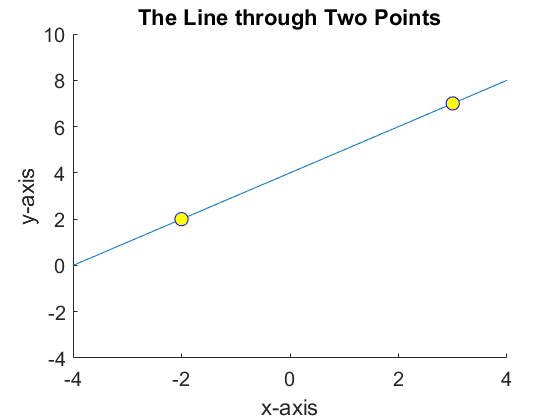


x=[x1 x2];
y=[y1 y2];



xlim = get(gca,'XLim');
m = (y(2)-y(1))/(x(2)-x(1));
n = y(2)*m - x(2);
y1 = m*xlim(1) + n;
y2 = m*xlim(2) + n;
hold on
line([xlim(1) xlim(2)],[y1 y2])

hold on
plot(x,y,'ob','MarkerSize',10,'MarkerFaceColor','yellow')
axis([-4 4 -4 10])
title('The Line through Two Points')
xlabel('x-axis')
ylabel('y-axis')
set(gca,'fontsize',15)
hold off




x1 = -2; y1 = 2;   % point #1 
x2 = +3; y2 = 7;   % point #2 


y=[y1;y2];

D=[1 x1; 1 x2];

y=[y1;y2];

D2=transpose(D)*D

D2 =      2     1
     1    13




b=inv(D2)*transpose(D)*y

b =     4.0000
    1.0000




x1 = -2; y1 = 2;   % point #1 
x2 = +3; y2 = 7;   % point #2
x3 = 0; y3 = 4;    % point #3

y=[y1;y2;y3];

D=[1 x1; 1 x2; 1 x3];

AM = [D y];

RAM= rref(AM)

RAM =      1     0     4
     0     1     1
     0     0     0



b = [RAM(1, 3); RAM(2, 3)] 

b =      4
     1



b=inv(transpose(D)*D)*transpose(D)*y

b =     4.0000
    1.0000



x1 = -2; y1 = 2;   % point #1 
x2 = +3; y2 = 7;   % point #2
x3 = 0; y3 = 6;    % point #3

y=[y1;y2;y3];

D=[1 x1; 1 x2; 1 x3];

AM = [D y];

RAM= rref(AM)

RAM =      1     0     0
     0     1     0
     0     0     1



b = [RAM(1, 3); RAM(2, 3)] 

b =      0
     0


b=inv(transpose(D)*D)*transpose(D)*y

b =     4.6842
    0.9474




y_est=D*b

y_est =     2.7895
    7.5263
    4.6842



e=y-y_est

e =    -0.7895
   -0.5263
    1.3158



e_rms=((1/3)*transpose(e)*e)^1/2

e_rms = 0.4386



x1 = -2; y1 = 2;   % point #1 
x2 = +3; y2 = 7;   % point #2
x3 = 0; y3 = 6;    % point #3

y=[y1;y2;y3];

D=[1 x1 (x1)^2; 1 x2 (x2)^2; 1 x3 (x3)^2];

b=inv(transpose(D)*D)*transpose(D)*y

b =     6.0000
    1.3333
   -0.3333



sea_level_data = importdata('-pastespecial');


filename = 'sea_level_data_Feb2020.mat';
save(filename)

clear, clc

filename = 'sea_level_data_Feb2020.mat';
load(filename)

time = sea_level_data(:,3);
gmsl11 = sea_level_data(:,11);
gmsl12 = sea_level_data(:,12);

first = [time(1), gmsl11(1),  gmsl12(1)]

first = 	1.0e+03 *

    1.9930   -0.0370   -0.0376


N = numel(time)

N = 988

last = [time(N), gmsl11(N), gmsl12(N)] 

last = 	1.0e+03 *

    2.0198    0.0624    0.0571



p1=plot(time,gmsl11,'Color','cyan')

p1 =   Line with properties:

              Color: [0 1 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×988 double]
              YData: [1×988 double]
              ZData: [1×0 double]

  Show all properties


hold on
p2=plot(time,gmsl12,'Color','blue')

p2 =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×988 double]
              YData: [1×988 double]
              ZData: [1×0 double]

  Show all properties


title('Global Mean Sea Level Radar Altimetry Data')
xlabel('Year')
ylabel('GMSL')
grid on
set(gca,'FontSize',13)
axis([1990 2025 -40 80])
p3=plot(time,(gmsl11 - gmsl12),'Color','magenta')

p3 =   Line with properties:

              Color: [1 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×988 double]
              YData: [1×988 double]
              ZData: [1×0 double]

  Show all properties


hold on





D=[ones(size(time)) time]

D = 	1.0e+03 *

    0.0010    1.9930
    0.0010    1.9930
    0.0010    1.9931
    0.0010    1.9931
    0.0010    1.9931
    0.0010    1.9931
    0.0010    1.9932
    0.0010    1.9932
    0.0010    1.9932
    0.0010    1.9933



y=gmsl12

y =   -37.5500
  -38.0600
  -37.6000
  -37.4500
  -36.4400
  -35.3100
  -34.2800
  -33.5000
  -32.9400
  -32.6000



b=inv(transpose(D)*D)*transpose(D)*y

b = 	1.0e+03 *

   -6.6309
    0.0033



y_est=D*b

y_est =   -38.0617
  -37.9718
  -37.8820
  -37.7921
  -37.7022
  -37.6124
  -37.5225
  -37.4326
  -37.3428
  -37.2529




p4=plot(time,y_est,'-r','LineWidth',3)

p4 =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 3
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×988 double]
              YData: [1×988 double]
              ZData: [1×0 double]

  Show all properties




hold on


t0 = sum(time)/numel(time) 

t0 = 2.0064e+03

y=gmsl12

y =   -37.5500
  -38.0600
  -37.6000
  -37.4500
  -36.4400
  -35.3100
  -34.2800
  -33.5000
  -32.9400
  -32.6000


D = [ones(size(time)) time-t0 (time-t0).^2]; 
b=inv(transpose(D)*D)*transpose(D)*y

b =     3.2603
    3.3079
    0.0506


y_est=D*b

y_est =   -32.0018
  -31.9488
  -31.8957
  -31.8425
  -31.7893
  -31.7359
  -31.6825
  -31.6291
  -31.5755
  -31.5219



p5=plot(time,y_est,'--k','LineWidth',2)

p5 =   Line with properties:

              Color: [0 0 0]
          LineStyle: '--'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×988 double]
              YData: [1×988 double]
              ZData: [1×0 double]

  Show all properties


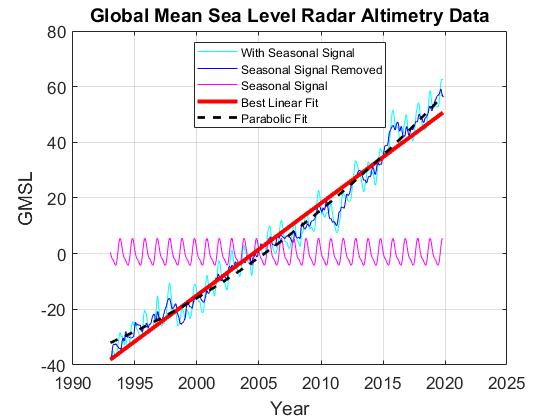


legend([p1 p2 p3 p4 p5],{'With Seasonal Signal','Seasonal Signal Removed','Seasonal Signal','Best Linear Fit','Parabolic Fit'},'FontSize',9,'Location','north')


GMSL = @(year) b(1) + b(2) * (year-t0) + b(3) * (year-t0).^2 

GMSL = function_handle with value:
    @(year)b(1)+b(2)*(year-t0)+b(3)*(year-t0).^2
